clear;clc
load xi_1_mean_ave10
load xi_1_lower_ave10
load xi_1_upper_ave10

% load('Sx\omega_VaryingEndpoint.mat')
% load('Sx\lambda_VaryingEndpoint.mat')

load('Sx\omega.mat')
load('Sx\lambda.mat')
load('Sx\omega_upper_bound.mat')
load('Sx\lambda_upper_bound.mat')
load('Sx\omega_lower_bound.mat')
load('Sx\lambda_lower_bound.mat')
load('Sx\cc.mat')
load('Sx\dd.mat')   
load('Sx\S.mat')
load('Sx\S_uncert.mat')

load('J1.mat')
load('J1_uncert.mat')



J1_seq=reshape(J1_seq,[70,1]);
max(J1_seq)

ans = 1.4992e+03

min(J1_seq)/max(J1_seq)

ans = 0.9571

J_bar=mean(J1_seq)*1e-3; %in kHz
mean_omega=mean(omega)/J_bar;
mean_lambda=mean(lambda)/J_bar;

upperbar_omega=(max(omega_upper_bound)-mean(omega))/J_bar;
upperbar_lambda=(max(lambda_upper_bound)-mean(lambda))/J_bar;
lowerbar_omega=(-min(omega_lower_bound)+mean(omega))/J_bar;
lowerbar_lambda=(-min(lambda_lower_bound)+mean(lambda))/J_bar;

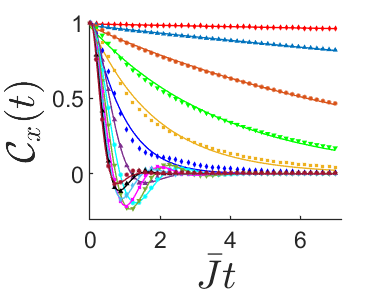

figure()
color={"#FF0000"
    "#0072BD"
    "#D95319"
    "#00FF00"
    "#EDB120"
    "#0000FF"
    "#7E2F8E"
    "#00FFFF"
    "#77AC30"
    "#FF00FF"
    "#4DBEEE"
    "#000000"
    "#A2142F"
    };
% color={    [20 81 124]/255
%         [216 56 58]/255
%     [150 195 125]/255
%     [243 210 102]/255
%     [247 225 237]/255
%     [47 127 193]/255
%     [231 239 250]/255
%     [248 243 249]/255
%     [169 184 198]/255
%     [196 151 178]/255
%     [147, 148, 231]/255
%     [0.814723686393179	0.905791937075619	0.126986816293506]
%     [0.913375856139019	0.632359246225410	0.0975404049994095]
%     };

% color={   rand(1,3)
%         rand(1,3)
%     rand(1,3)
%     rand(1,3)
%     rand(1,3)
%     rand(1,3)
%     rand(1,3)
%     rand(1,3)
%     rand(1,3)
%    rand(1,3)
%     rand(1,3)
%    rand(1,3)
%    rand(1,3)
%     };
marker=flip({'.','^','d','s','v','.','^','d','s','v','.','^','d'});
markersize=flip([5,1,1,1,1,5,1,1,1,1,5,1,1])*1;
ii=1;
endpoint=41;
for i=[1:13]

    tau=5*1e-6;
    td1=41;
    quench_time_seq=24*tau*(0:td1-1)*1e3; %in ms

    x=quench_time_seq(1:endpoint);
    y=S(i,1:endpoint)';

    errorbar(x*J_bar,y,FID_uncertainty(i,1:endpoint),marker{ii},'MarkerSize',markersize(ii),'MarkerFaceColor',color{ii},'Color',color{ii},'CapSize',1);
    hold on
    xx=0:1e-2:x(end);
    y_fit=cc(end,i)*cos(2*pi*omega(end,i)*xx+dd(end,i)).*exp(-2*pi*lambda(end,i)*xx);
    plot(xx*J_bar,y_fit,'color',color{ii})
    ii=ii+1;
end

xlabel('$\bar{J}t$','Interpreter','latex','FontSize',15)
ylabel('$\mathcal{C}_x(t)$','Interpreter',"latex",'FontSize',15)
ylim([-0.3 1])
yticks([-0.5 0 0.5 1])
yticklabels({'-0.5', '0', '0.5', '1'})
xlim([0 7.2])
xticks([0:2:6])
% fontsize(gcf,10,'points')
% fontname(gcf,"Helvetica")
set(gcf,'unit','centimeters','position',[10,10,5,4]);

set(gca,"box",'off')
saveas(gcf,'figures/a1.pdf')


xi_3=0.2;
xi_1=xi_1_mean';
xi_2=-xi_3-xi_1;
A=-6*xi_3.*xi_2;
B=xi_1.^2+xi_2.^2+xi_3.^2;
omega_theo=real(sqrt(A));
lambda_theo=sqrt(B)-(1-sign(A))/2.*sqrt(-A);

y=[mean_omega,mean_lambda]';
x=[omega_theo;lambda_theo];
[xData, yData] = prepareCurveData(x, y);

% 设置 fittype 和选项。
ft = fittype( 'c*x', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = 0.890903252535798;

% 对数据进行模型拟合。
[fitresult, gof] = fit( xData, yData, ft, opts )

fitresult =      General model:
     fitresult(x) = c*x
     Coefficients (with 95% confidence bounds):
       c =      0.9113  (0.842, 0.9806)

gof = 包含以下字段的 struct :
           sse: 0.0892
       rsquare: 0.9284
           dfe: 25
    adjrsquare: 0.9284
          rmse: 0.0597


conf=confint(fitresult)

conf =     0.8420
    0.9806


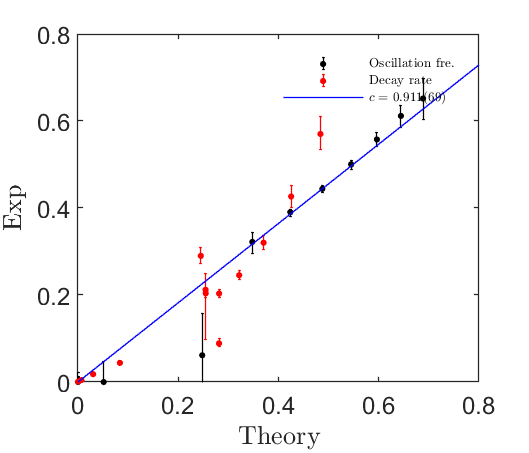

scale=fitresult.c;
scale_error=1/2*(conf(2)-conf(1));

% 绘制数据拟合图。
figure()
errorbar(omega_theo,mean_omega,lowerbar_omega,upperbar_omega,...
    '.','Markersize',8,'color','k','CapSize',1)
hold on
errorbar(lambda_theo,mean_lambda,lowerbar_lambda,upperbar_lambda,...
    '.','Markersize',8,'color','r','CapSize',1)
hold on
plot(0:1e-3:1,fitresult(0:1e-3:1),'-','Color','b')

xlim([0 0.8])
ylim([0 0.8])
xlabel('Theory','Interpreter','latex')
ylabel('Exp','Interpreter','latex')

legend('Oscillation fre.','Decay rate',['$c=',num2str(round(scale,3)),'(',num2str(1e3*round(scale_error,3)),')$'],'interpreter','latex','box','off','fontsize',5)
% fontsize(gcf,10,'points')
% fontname(gcf,"Times New Roman")
set(gcf,'unit','centimeters','position',[10,10,7,6]);
set(gca,'XTickLabelRotation',0)

xi1_continuous=-0.4:1e-3:0.2;
xi_3=0.2;
xi_1=xi1_continuous';
xi_2=-xi_3-xi_1;
A=-6*xi_2.*xi_3;
B=xi_1.^2+xi_2.^2+xi_3.^2;

omega_fit=scale*real(sqrt(A));
lambda_fit=scale*sqrt(B)-(1-sign(A))/2.*sqrt(-A);

% omega_fit=c1*real(sqrt(A));
% lambda_fit=c2*sqrt(B)-c1*(1-sign(A))/2.*sqrt(-A);

x=xi_1_mean';
y=mean_omega;
fprintf('%f,',mean_omega);fprintf('\n');

0.000000,0.000000,0.000000,0.000000,0.000000,0.061514,0.322001,0.390372,0.444140,0.500247,0.557671,0.611718,0.651831,


fprintf('%f,',lowerbar_omega);fprintf('\n');

0.008000,0.011189,0.012475,0.020972,0.046999,0.108189,0.026153,0.009615,0.009624,0.010831,0.015550,0.026250,0.048621,


fprintf('%f,',upperbar_omega);fprintf('\n');

0.008000,0.011189,0.012476,0.020972,0.046998,0.094850,0.022317,0.006787,0.006796,0.009305,0.014810,0.025002,0.045004,


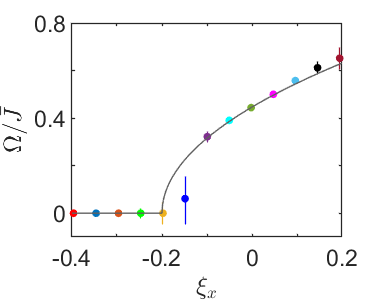

figure()
for i=1:13
    errorbar(x(i),y(i),lowerbar_omega(i),upperbar_omega(i),xi_1_lower(i),xi_1_upper(i),...
        '.','Markersize',10,'color',color{i},'Markerfacecolor',color{i},'CapSize',0)
    hold on
end
plot(xi1_continuous,omega_fit,'-','Color',[96 96 96]/255)

xlim([-0.4 0.2])
xticks([-0.4:0.1:0.2])
xticklabels({'-0.4','','-0.2','','0','','0.2'})
ylim([-0.1 0.8])
yticks([0:0.2:0.8])
yticklabels({'0','','0.4','','0.8'})
xlabel('$\xi_x$','Interpreter','latex')
% ylabel('Fitted oscillation frequency $\omega/J$','Interpreter','latex')
ylabel('$\Omega/\bar{J}$','Interpreter','latex')

% title('The color gradient indicates varying $\xi_x$','Interpreter',"latex",'FontSize',16)
% legend('',['$c*\sqrt{A},\ c=',num2str(round(scale,3)),'(',num2str(1e3*round(scale_error,3)),')$'],'interpreter','latex','box','off','fontsize',5)
% legend('',['$c=',num2str(round(scale,3)),'(',num2str(1e3*round(scale_error,3)),')$'],'interpreter','latex','box','off','fontsize',5)

% fontsize(gcf,10,'points')
% fontname(gcf,"Helvetica")

set(gcf,'unit','centimeters','position',[10,10,5,4]);
set(gca,'XTickLabelRotation',0)
saveas(gcf,'figures/a2.pdf')

x=xi_1_mean';
y=mean_lambda;

fprintf('%f,',mean_lambda);fprintf('\n');

0.000773,0.004490,0.017971,0.043814,0.088777,0.211996,0.289927,0.203815,0.203483,0.245510,0.320153,0.426568,0.570162,


fprintf('%f,',lowerbar_lambda);fprintf('\n');

0.000226,0.000409,0.001011,0.002949,0.006965,0.115077,0.018534,0.010027,0.009224,0.010813,0.015823,0.024338,0.036807,


fprintf('%f,',upperbar_lambda);fprintf('\n');

0.000372,0.001038,0.001921,0.004765,0.012162,0.036519,0.019982,0.007466,0.008050,0.010583,0.016157,0.025984,0.039804,


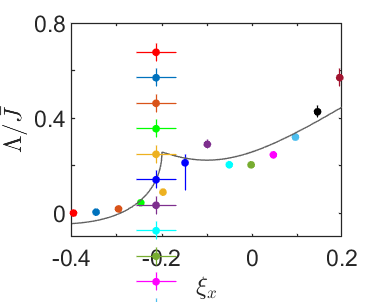


figure()
for i=1:13
    errorbar(x(i),y(i),lowerbar_lambda(i),upperbar_lambda(i),xi_1_lower(i),xi_1_upper(i),...
        '.','Markersize',10,'color',color{i},'CapSize',0)
    hold on
end
plot(xi1_continuous,lambda_fit,'-','Color',[96 96 96]/255)
xlim([-0.4 0.2])
xticks([-0.4:0.1:0.2])
xticklabels({'-0.4','','-0.2','','0','','0.2'})
ylim([-0.1 0.8])
yticks([0:0.2:0.8])
yticklabels({'0','','0.4','','0.8'})
xlabel('$\xi_x$','Interpreter','latex')
% ylabel('Fitted oscillation frequency $\omega/J$','Interpreter','latex')
ylabel('$\Lambda/\bar{J}$','Interpreter','latex')

% title('The color gradient indicates varying $\xi_x$','Interpreter',"latex",'FontSize',16)
% legend('',['$c*\sqrt{A},\ c=',num2str(round(scale,3)),'(',num2str(1e3*round(scale_error,3)),')$'],'interpreter','latex','box','off')
legend('','','','','','','','','','','','','',['$c=',num2str(round(scale,3)),'(',num2str(1e3*round(scale_error,3)),')$'],'interpreter','latex','box','off')
% legend({'','','','','','','','','','','','',['$c_1=',num2str(round(c1,3)),'(',num2str(1e3*round(c1_error,3)),')$'], ['$c_2=',num2str(round(c2,3)),'(',num2str(1e3*round(c2_error,3)),')$']},'interpreter','latex','box','off')

% fontsize(gcf,10,'points')
% fontname(gcf,"Helvetica")

set(gcf,'unit','centimeters','position',[10,10,5,4]);
set(gca,'XTickLabelRotation',0)
saveas(gcf,'figures\a3.pdf')